## Introduction

This notebook is intended as a guide for using MATLAB and the code I've developed to determine the areas of transient instability that may lead to Turing pattern formation for different reaction networks. The work is based off of the network atlas approach undertaken by Scholes *et al.* (*Cell Systems* (2019), **9** (3), 243-257) and the Turing conditions for pattern formaiton on growing domains proven by Van Gorder *et al.* (*J. Math. Bio. *(2021), **82** (4)). 

## Objective

Our objective is to determine the areas in parameter space where Turing patterns may be able to form for all of the two-node reaction networks on growing domains. 

## Approach

Our approach is to systematically test every network by using both the competitive and noncompetitive Hill functions on growing domains. That is, we will scan through multiple parameters and see where the Turing instability conditions are met for a variety of growing systems.

For each simulation set, we will create a new 'NetSim' object that contains the parameter set, the Hill reactions, and the growth rate (if any). The time-limiting step will be to simulate (in time) the evolution of the homogeneous state. However, after this, testing the Turing instabiltiy conditions should be relatively fast, so each object will have multiple diffusion coefficents that it can test. 

Once we have finished testing the object, we then will store the results in some sort of database, or at least in some systematic manner. However, I'm still working on this now, so we'll have to see what I can come up with.

## Code

Now, onto the important start - the code that I've developed and an explanation on how it works. First off, we need to initialize the object in one of two ways - either calling it with the full (required) constructor arguments or just filling it in after the fact. Either work really - you just need to make sure to have (at the end of initialization) a parameter set, the reaction equations, a growth mode, and a growth parameter.

## Initialization Method 1: Call full constructor. Note: see code for descriptions of the optional parameters you can call (and their order)

% exampleObj = NetSim([0.1 0.5],{@(x,k)k(1)-x(1)+x(1)^2*x(2),@(x,k)k(2)-x(1)^2*x(2)},'Exponential',0.01);

% Variable arguments (varargin) - dvals, init_size, final_size
% These will default to the normal values if not specified


## Initialization Method 2: Initialize object then fill in values as needed

exampleObj = NetSim;
exampleObj.k_params = [0, 1.1]; % Vector of reaction parameters
exampleObj.rxn_funcs = {@(x,k)k(1)-x(1)+x(1)^2*x(2),@(x,k)k(2)-x(1)^2*x(2)}; % Cell array of anonymous functions
exampleObj.grow_type = 'Exponential'; % String, 'Exponential' and 'Linear' are the only viable options. Will add 'Logistic' later
exampleObj.grow_param = 0.01; %Scalar value of growth parameter
%exampleObj

Once you fill in all of these four values, most of the rest of the object should "fill in" - the other properties are Dependent, so they don't actually exist. Instead, I've written a "get" function for all of them that will define it. As of now, the only two remaining values that don't form automatically are "base_state" and "homo_state" - these I will explain below.

## Determining the "Base" and "Homogeneous" States

Now that the simulation (object) is initialized, we can actually start running the analysis that Van Gorder *et al.* presented. First, we need to determine the behavior of the homogeneous state (not spatially extended) in time while the domain grows. To do this, we can numerically simulate the time evolution of the homogeneous state for the period of time when the system grows (from initial size to final size).

First, to determine the initial condition, we look to the steady state solution of just the reaction system (without any growth). This can be done using the following function:

tic;
exampleObj.base_state = exampleObj.solveBaseState();
toc

Elapsed time is 0.040301 seconds.


exampleObj.base_state

ans =     1.1000    0.9091


This will yield an m x n array, where n is the number of variables and m is the number of solutions to the base state. Currently nothing happens if the base state doesn't exist (no solution) - I'll probably work in a fix or default into the ODE code (below).

Next, we need to use this base state as the initial condition for the ODE simulation, which includes how the domain growth term. In some instances, it may just stay at the base state, while others the homogeneous state may be oscialltory or unstable. Either of these are fine - the code to test where the instabilities are should work with it all (hopefully).

tic;
exampleObj.homo_state = exampleObj.homogeneousStateSim();
toc

Elapsed time is 47.194044 seconds.


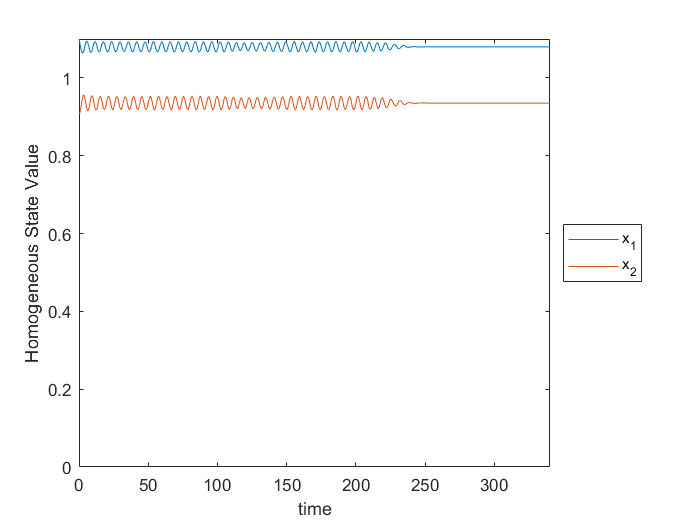

t_vec = exampleObj.homo_state{1,1};
conc_vals = exampleObj.homo_state{1,2};
conc_vec1 = conc_vals(:,1);
conc_vec2 = conc_vals(:,2);
plot(t_vec,conc_vec1,t_vec,conc_vec2)
xlabel('time')
ylabel('Homogeneous State Value')
xlim([0 inf])
ylim([0 inf])
legend({'x_1','x_2'},'Location','eastoutside')

The homogeneous state (exampleObj.homo_state) is a mx2 cell array. The first column of cells contains the time vectors of each simulation, and the second column contains matrices with n columns (number of variables) and the rows correspond to the points in time. In the above code I plot both variables to demonstrate, though this certainly isn't necessary to complete the simulations.

## Testing the Turing Condition

Now, we are finally in a position to actually use the results from Van Gorder *et al*. His main result is Theorem 3 in his paper, which is far too long to write up here. Essentially, it gives a new condition that defines where transient Turing-type instabilites can form on a growing domain. This was very tricky to code up, as it requires multiple time-derivatives of the Jacobian elements as well as a bunch of other analysis. However, I have compiled it down into a single parent function, which successfully gives the proper results (though there is a lot going on underneath the hood here) where you only need to include one parameter - the diffusion ratio of `d = d_2 / d_1`. The "standard" value would be 10, though we will have to test many different values for our studies.

%turingSpace = exampleObj.findTuringSpace(10);
tic;
turingSpace = exampleObj.findTuringSpace_new(10);
toc

Elapsed time is 1.637100 seconds.


Note that I have commented out the first line - the initial parent function I developed to do this task. Because this function is very complex (and I'm not that good at optimizing MATLAB), running this code takes a long time - approximately 15 minutes on my laptop. While this is unacceptably long for any serious simulations, the method this code uses is a bit easier to understand and trace through the various functions. However, it is very unoptimized. Instead, it is better to use the `obj.findTuringSpace_new` function, which is much further optimized and can run in about 1.7 seconds. The major difference is that I preset all of the functions (the ones that required symbolic math to create) and now only use the anonymous function calls. It's much faster, but harder to understand. So, I will be using that method for actual simulations.

If instead you just want to look at a previous result, you can use the lines of code below. It is the same conditions (and therefore the same figure) as Van Gorder's Figure 1, condition a.

%ex = load('VG_1_a_iii.mat');
%turingSpace = ex.exampleResult;

From here, we can visualize the results as in below.

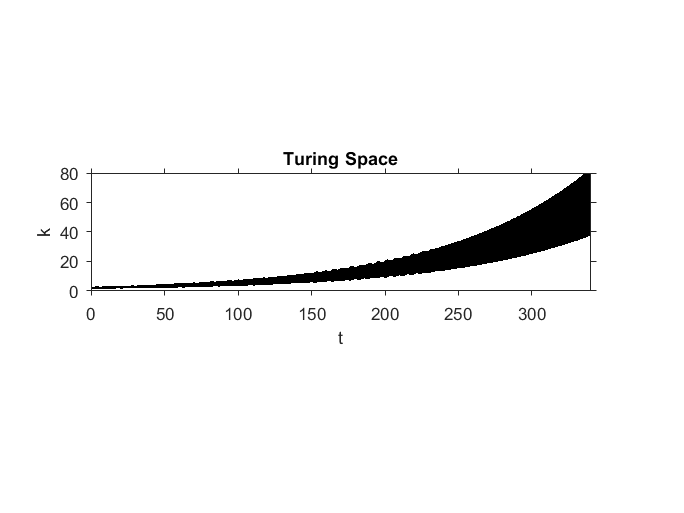

fig = figure;

%Determine axis bounds
[r, c] = size(turingSpace);

maxT = exampleObj.t_final;
maxk = max(exampleObj.k_vec);

imshow(flipud(turingSpace), 'XData', [0 round(maxT/4) round(maxT/2) round(3*maxT/4) round(maxT)],...
    'YData', [0 round(maxk/4) round(maxk/2) round(3*maxk/4) round(maxk)])
set(gca,'YDir','normal')

axis on

%Label Plot
xlabel('t')
ylabel('k')

title('Turing Space')